# Example - Zeeman Map

clear all
addpath("Molecules\");addpath("Atoms\")
C = Constants;
set(groot,'defaultAxesXGrid','on')
set(groot,'defaultAxesYGrid','on')
set(groot,'defaultAxesBox','on')
set(groot,'defaultAxesLineWidth',0.5)

## Define Fields

maxN = 1;
B.value = [1e-6:0.5:20];
B.dir = [0,0,1];
B.scaling = 1e-4; %put B.value in Gauss, not Tesla
E.value = [0]; %V/m
E.dir = [0,0,1];
E.scaling = 1e2;%put E.value in V/cm, not V/m
I.value = [0];
I.dir = [0,0,1];
I.pol = [1,0,0];
I.scaling = 1e7;%put I.value in mW/cm^2, not W/m^2
Fields.B = B;
Fields.E = E;
Fields.I = I;

## Define Hamiltonian

Mol = KRb(40,87);
Ham = Hamiltonian(Molecule = Mol, Fields=Fields, maxN=maxN);
H0 = Ham.hyperfine.total + I.value*I.scaling*Ham.ac_stark + E.value*E.scaling*Ham.dc_stark;
Base = Ham.Basis;
nStates = Base.NStates;

## Diagonalise for varying intensity

F = B;
x = B.value;
energyMap = nan(length(x),nStates);
statesMap = nan(length(x),nStates,nStates);
for k = 1:length(x)
    if mod(k,10)==1; fprintf("%d - ",k); end
    H = H0 + x(k)*B.scaling*Ham.zeeman;
    [V,D] = eig(full(H/C.h),'vector'); %no need to use sparse matrices for matrices smaller than 1000x1000. Divide by Plancks constant to get energy in Hz
    [d,sortIdx] = sort(real(D));
    energyMap(k,:)=d;        
    statesMap(k,:,:) = V(:,sortIdx);
end

1 - 11 - 21 - 31 - 

energyMap = energyMap*1e-6;
disp("Finished")

Finished


## Plot Results

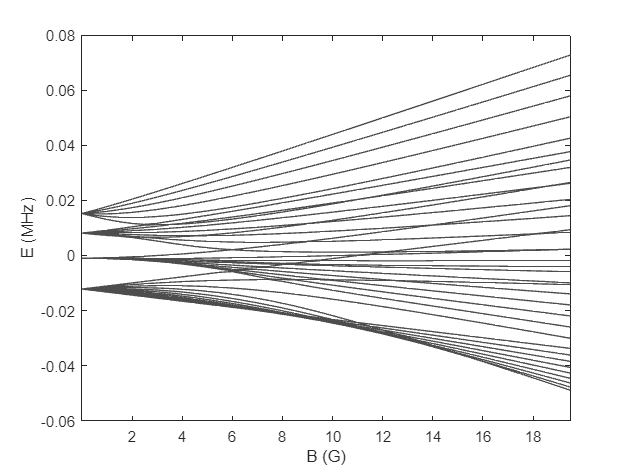

N = Base.getStates("N");
figure(13); clf;
plot(x,energyMap(:,N==0), color=[1,1,1]*0.3); hold on;
xlabel("B (G)")
ylabel(sprintf("E (MHz)"))
% ylim([-1.5,1])
xlim([min(x),max(x)])
grid off

## Induced Magnetic Moment

If we evaluate the magnetic moments straight from the eigenstates, we get something very messy

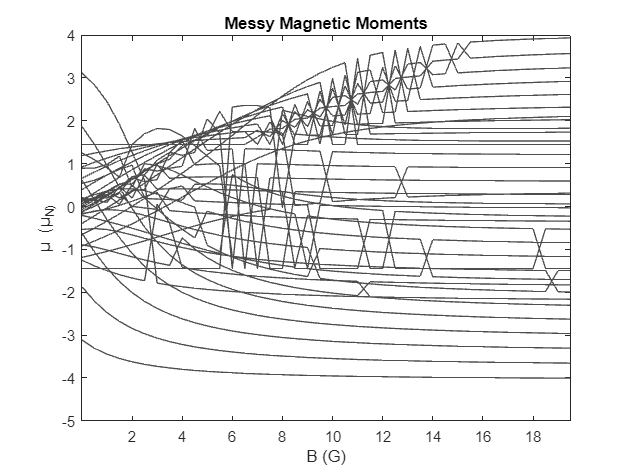

mu = nan(size(energyMap));
psis = statesMap;
for k = 1:length(x)
    psi = squeeze(psis(k,:,:));
    mu(k,:) = diag(conj(psi')*Ham.zeeman*psi); %expectation value of zeeman part of the Hamiltonian
end
muEffective = -real(mu)/Constants.muN;

N = Base.getStates("N");
figure(14); clf;
plot(x,muEffective(:,N==0), color=[1,1,1]*0.3); hold on;
xlabel("B (G)")
ylabel(sprintf("µ (µ_N)"))
% ylim([-1.5,1])
xlim([min(x),max(x)])
grid off
title("Messy Magnetic Moments")

To clean this up, we first have to sort the states by following the diabats (the curve in which the wavefunction changes the least when going through a crossing). Since a lot of states are degenerate at B=0, we start from the last value of x (which has index=length(x)). The function adiabat returns both the diabats and the adiabats.

diabatStates = nan(size(statesMap));
diabats = nan(size(energyMap));
for stIdx = 1:size(statesMap,3)
    [diabat, diabatState, ~, ~] = findAdiabat(x,energyMap,statesMap, length(x),stIdx); 
    diabats(:,stIdx) = diabat;
    diabatStates(:,:,stIdx) = diabatState;
end

for k = 1:length(x)
    psi = squeeze(diabatStates(k,:,:));
    mu(k,:) = diag(conj(psi')*Ham.zeeman*psi); %expectation value of zeeman part of the Hamiltonian
end
muEffectiveSorted = -real(mu)/Constants.muN;

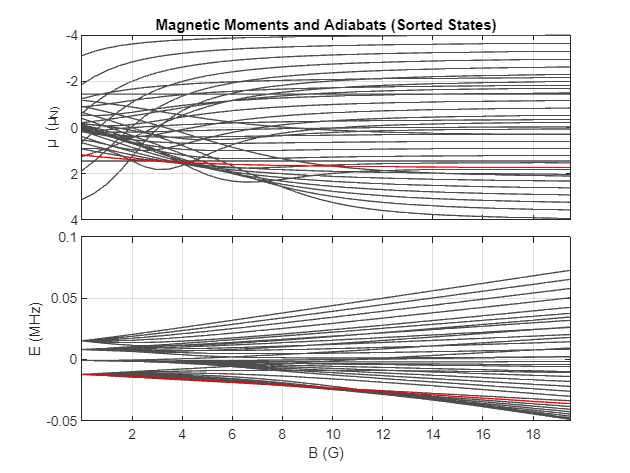

selectDiabat = 8;
N = Base.getStates("N");
figure(15); clf;
t = tiledlayout(2,1, TileSpacing="tight");
nexttile(); %plot induced magnetic dipole
plot(x,muEffectiveSorted(:,N==0), color=[1,1,1]*0.3); hold on;
plot(x,muEffectiveSorted(:,selectDiabat), color=[1,0,0])
set(gca,YDir='reverse')
ylabel(sprintf("µ (µ_N)"))
xlim([min(x),max(x)])
xticklabels([])
title("Magnetic Moments and Adiabats (Sorted States)")

nexttile(); %plot sorted states with diabat
plot(x,diabats(:,N==0), color=[1,1,1]*0.3); hold on;
plot(x,diabats(:,selectDiabat), color=[1,0,0])
xlabel("B (G)")
ylabel(sprintf("E (MHz)"))
xlim([min(x),max(x)])